# Project 6 (Aircraft Descent Profile)

%{
Aircraft descent profile
   originally from ES115 Engineering Computer Applications, Module 2
   project bank, project 12
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -to model the phases of descent for an aircraft that is landing
Input:
   -
Output:
   -altitude vs time plot
   -speed vs time plot
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   -
%}

clc
clear

% define initial cruising speed and target landing altitude
ICv = 240; % the initial cruising speed in m/s
IAlt = 10000; % the initial altitude in m
targetH = 0; % the target landing altitude in m

% simulate vertical descent while enforcing maximum and minimum speed
%constraints
vMax = 260; % defines max speed
vMin = 0; % defines minimum speed
t = 0:1:2000; % defines the interval of time
dt = 1; % step size of time
% defines the altitude, speed, and vertical speed
alt = zeros(size(t)); 
spd = zeros(size(t));
vs = zeros(size(t));
alt(1) = 10000;
spd(1) = 240;

for i = 2:length(t)
    if alt(i-1) <= targetH
        alt(i:end) = targetH;
        spd(i:end) = spd(i-1);
        break
    end
     if alt(i-1) > 3000
        vs(i) = -15;
    elseif alt(i-1) > 1000
        vs(i) = -5;
    else
        vs(i) = -2;
     end
      alt(i) = alt(i-1) + vs(i)*dt;
      spd(i) = spd(i-1) - 0.05;
        spd(i) = max(min(spd(i), vMax), vMin);
    
end
valid = alt > targetH | [true diff(alt)~=0];
t = t(valid);
alt = alt(valid);
spd = spd(valid);

% identify the phases of descent
steadyD = alt > 3000; % defines steady descent for when altitude is greater than 3000
levelingD = alt <= 3000 & alt > 1000; % defines the leveling descent for when altitude is less than/equal to 3000 and greater than 1000
finalA = alt <= 1000; % defines the final approach when the altitude is less than/equal to 1000

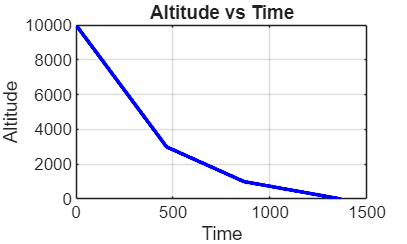

% plots the altitude vs time
plot(t, alt, 'b-', 'LineWidth', 2) % the line is blue with a width of 2
title('Altitude vs Time') % creates a title for the graph
xlabel('Time') % labels the x-axis as 'time'
ylabel('Altitude') % labels the y-axis as 'altitude'
grid on  % turns the grid lines on

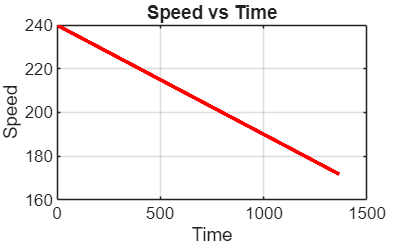

% plots speed vs time
plot(t, spd, 'r-', 'LineWidth', 2) % the line is red with a width of 2
title('Speed vs Time') % creates a title for the plot
xlabel('Time') % labels the x-axis 'time'
ylabel('Speed') % labels the y-axis 'speed'
grid on % turns the grid lines on for the plot

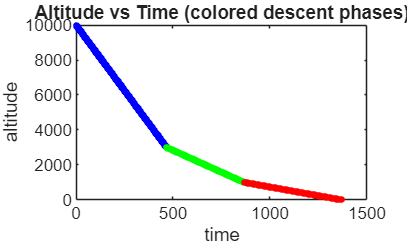

% colored phase plot for altitude to show the phases of descent
figure
plot(t(steadyD), alt(steadyD), 'b.', 'MarkerSize', 10, 'DisplayName', 'Steady Descent') % plots the steady descent phase for altitude vs time
hold on % allows the following plots to be on the same graph
plot(t(levelingD), alt(levelingD), 'g.', 'MarkerSize', 10, 'DisplayName', 'Leveling') % plots the leveling descent phase for atltitude vs time
plot(t(finalA), alt(finalA), 'r.', 'MarkerSize', 10, 'DisplayName', 'Final Approach') % plots the final approach phase for altitude vs time
hold off % stops holding on for more plots to be graphed on the plane
title('Altitude vs Time (colored descent phases)') % creates a title for the graph
xlabel('time') % labels the x-axis 'time'
ylabel('altitude') % labels the y-axis 'altitude